# Descriptors per cada senyal

Aqui podem veure com apliquem els descriptors a les senyals model:

llindarParaleles = 20;
dibuixar = false;

for senyal=0:42
    iActual = imread(strcat("Models\Meta\", int2str(senyal),'.png'));   
    %iBW = imbinarize(iActual);
    iRectas = buscarRectas(iActual, false,5);
    
    descriptors(senyal+1).pendientes = calcParaleles(iActual);
    descriptors(senyal+1).nombre = numberToName(senyal+1);
    descriptors(senyal+1).liniesParaleles = range([iRectas.theta])<= llindarParaleles;
        
    if dibuixar        
        figure 
        subplot(1,4,1)
        imshow(iActual);
        subplot(1,4,2)
        imshow(iBW(:,:,1));
        subplot(1,4,3)
        imshow(iBW(:,:,2));
        subplot(1,4,4)
        imshow(iBW(:,:,3));
    end
end

## myBinarize

Per detecar les senyals, podem veure que els colors blaus i vermells ens faciliten la feina.

- Un color vermell apareix com a blanc al binaritzar la capa R de la imatge original RGB

- Un color blau apareix com a blanc al binaritzar la capa B de la imatge original RGB

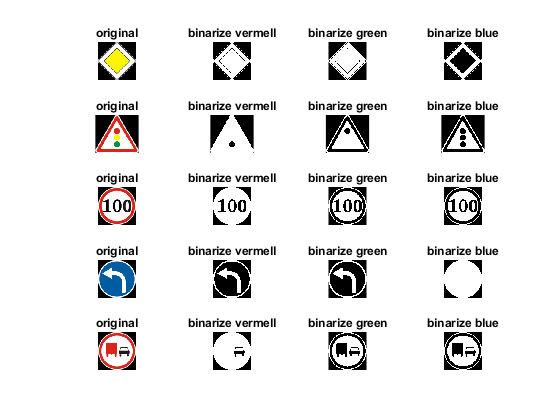

imgs = [12, 26, 7, 34, 10];
figure;
aux = 1;
numImatges = numel(imgs);
descripcions = 4;
for iterador=1:numImatges
    iActual = imread(strcat("Models\Meta\", int2str(imgs(iterador)),'.png'));
    
    subplot(numImatges,descripcions,aux);
    imshow(iActual); title("original");
    
    subplot(numImatges,descripcions,aux+1);
    iBW = imbinarize(iActual);
    imshow(iBW(:,:,1)); title("binarize vermell")
    
    subplot(numImatges,descripcions,aux+2);
    iBW = imbinarize(iActual);
    imshow(iBW(:,:,2)); title("binarize green")
    
    subplot(numImatges,descripcions,aux+3);
    iBW = imbinarize(iActual);
    imshow(iBW(:,:,3)); title("binarize blue")
    
    aux = aux + descripcions;
end

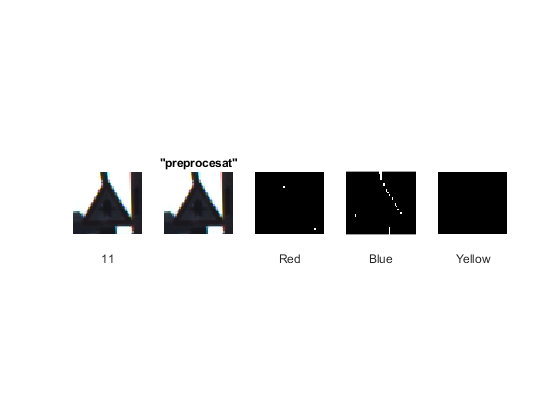

A = exist('ds', 'var');
if ~A
ds = imageDatastore(["Train1\Train1\", "Train2\Train2\"], "LabelSource","foldernames", "IncludeSubfolders",true);
ds = ds.shuffle();
end

figure
[data, info] = ds.read();

subplot(1,5,1);
imshow(data); xlabel(info.Label);

dataAdj = imadjust(data, [.0 .0 .0; 1 1 1]);
subplot(1,5,2);
imshow(dataAdj); title "preprocesat"

%mirar capas de color:
[iRed, iBlue, iYellow] = calcColors(dataAdj);
subplot(1,5,3);
imshow(iRed); xlabel("Red");

subplot(1,5,4);
imshow(iBlue); xlabel("Blue");

subplot(1,5,5);
imshow(iYellow); xlabel("Yellow");

## Text OCR

Les senyals de velocitat tenen text que podem llegir amb OCR:

%txt = ocr(imread("Models\Meta\3.png"))

## Color

Els colors son força significatius per totes les senyals. Els colors principals a tractar son el blau, el groc i el vermell.

- Color més predominant

- Presència de colors

- Forma + Color

imagenes = [12, 26, 7, 34];

'ocr' requires Computer Vision Toolbox.


figure;
aux = 1;
numImatges = numel(imagenes);
descripcions = 4;
for iterador=1:numImatges
    iActual = imread(strcat("Models\Meta\", int2str(imagenes(iterador)),'.png'));
    [iRed, iBlue, iYellow] = calcColors(iActual);
    subplot(numImatges,descripcions,aux);
    imshow(iRed);title vermell;
    ylabel(num2str(sum(iRed(:) == 1)))
    
    subplot(numImatges,descripcions,aux+1);
    imshow(iBlue);title blau
    ylabel(num2str(sum(iBlue(:) == 1)))
    
    subplot(numImatges,descripcions,aux+2);
    imshow(iYellow);title groc;
    ylabel(num2str(sum(iYellow(:) == 1)))
    
    subplot(numImatges,descripcions,aux+3);
    imshow(iActual); title original;
    
    aux = aux + descripcions;
end


## Hough

Podem aplicar la transformada de Hough per reconeixer les rectes, pero comparant el rang de les pendents de les rectes, d'aquesta manera ens permet discriminar les senyals amb linies rectes com la senyal 9 o 32.

Podem considerar aquest valor amb un llindar, 1 per valors de rang < 8 i 0 per valors superiors.

calcParaleles(imread("Models\Meta\6.png"));
calcParaleles(imread("Models\Meta\1.png"));
calcParaleles(imread("Models\Meta\32.png"));
calcParaleles(imread("Models\Meta\41.png"));
calcParaleles(imread("Models\Meta\42.png"));

## Forma circular, triangular, rombo

Tenim molta informació amb la forma exterior de la senyal i el seu color.

Podem detecar les figures geomètriques bàsiques amb les propietats de les regions blanques, sumat a una detecció del color ens permet:

aquesta propietat la podem emmagatzemar com un 0 o 1 directament per no arrosegar una variable categórica.

- esCercleVermell

- esRomboBlanc

- esTriangleInvertitVermell

- esRomboideBlanc

- esCercleBlanc

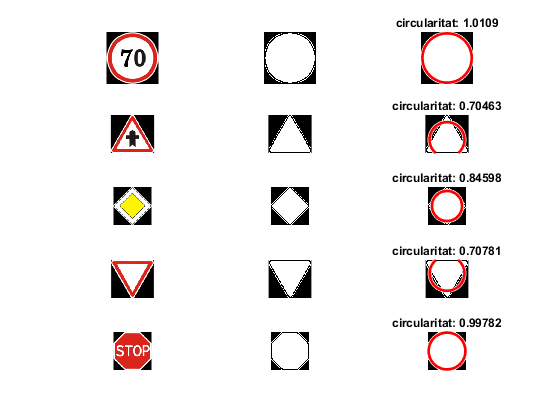

imagenes2 = [4, 11, 12, 13, 14];

figure;
aux = 1;
numImatges = numel(imagenes2);
descripcions = 3;

for iterador=1:numImatges
    img = imread(strcat("Models\Meta\", int2str(imagenes2(iterador)),'.png'));
    BW = rgb2gray(img);         %pasem a escala de grisos
    BW = edge(BW,'canny');      %resaltem les bores
    BW = imfill(BW, "holes");   %ens quedem amb la forma mes exterior
    
    stats = regionprops("table", BW,"all");
    [~,maxidx] = max(stats.Area);

    centers = stats.Centroid; 
    diameters = mean([stats.MajorAxisLength stats.MinorAxisLength],2); 
    radii = diameters/2;
    
    subplot(numImatges, descripcions, aux);
    imshow(img);
    
    subplot(numImatges,descripcions,aux+1);
    imshow(BW); 
    
    subplot(numImatges,descripcions,aux+2);
    imshow(BW); title(strcat("circularitat: ", num2str(stats.Circularity(maxidx))));
    hold on
    viscircles(centers(maxidx,:),radii(maxidx)); 
    hold off
    
    aux = aux + descripcions;
end

Un circulo tiene una circularidad casi de 1.

## Detecció de formes

Algunes de les senyals tenen formes caracteristiques (com coches, camions, pas de vianants, bicicleta, etc...)

Podriem fer patter-matching per intentar buscar aquestes formes.

https://es.mathworks.com/matlabcentral/fileexchange/24925-fast-robust-template-matching

[No le veo mucho futuro.]

## Àrea i altres estadístics de la imatge binària

Per discernir entre les diferents formes, podem optar per a calcular l'àrea total dels elements interiors a la senyal i dividits pel tamany de la senyal (així no tenim problemes amb el escalat).

[ToDo: explicar "elements interiors"]

Si no tenim cap element interior, doncs la senyal tindrà un valor de 0 i podrem classificar-la com 12, 13, 15 o similar segons la seva forma.